# Contribution 1 Script

This script allows for processing of raw Mindrove .csv files. This script process the EMG data, RMS, and envelope the RMS signal to then extract the peak values using findpeaks.

## Import Data and Standardize

Note: Must create column titled "timestamp_real" within csv file that changes timestamp column formatting: format -> custom->h:mm:ss->h:mm:ss.000

% NOTE: Must create column titled
%       "Timestamp_real" WITHIN 
%       EXCEL FILE that changes
%       "timestamp" column to:
%       format->custom->h:mm:ss

% File Selection
filename = ['5_09_11_26_30.csv']; %change this line before the .csv
tab = readtable(filename);
data = readmatrix(filename, 'NumHeaderLines', 1);

% Extract Data
time = tab.Timestamp_real(:,1); % cell array of time values
t = datetime(time,'InputFormat','mm:ss.SSS'); %datetime of time values
ch0_data = data(:,1);
ch1_data = data(:,2);
ch2_data = data(:,3);
ch3_data = data(:,4);
ch4_data = data(:,5);
ch5_data = data(:,6);
ch6_data = data(:,7);
ch7_data = data(:,8);
accx = data(:,11);
accy = data(:,12);
accz = data(:,13);

% Getting Acc in units of G [m^2/s]
accel_constant = 0.061035e-3; %constant converting Mindrove units to G
accx = accx*accel_constant;
accy = accy*accel_constant;
accz = accz*accel_constant;

% Getting EMG into units of muV
emg_constant = 0.045;
ch0_data = ch0_data*emg_constant;
ch1_data = ch1_data*emg_constant;
ch2_data = ch2_data*emg_constant;
ch3_data = ch3_data*emg_constant;
ch4_data = ch4_data*emg_constant;
ch5_data = ch5_data*emg_constant;
ch6_data = ch6_data*emg_constant;
ch7_data = ch7_data*emg_constant;

%Time Calculations
t = posixtime(t);
t = t - t(1);

## EMG / ACCEL DATA ANAYLYSIS VARIABLES

Peak Enveloping value

filtervalue = 100;

## EMG Data Analysis

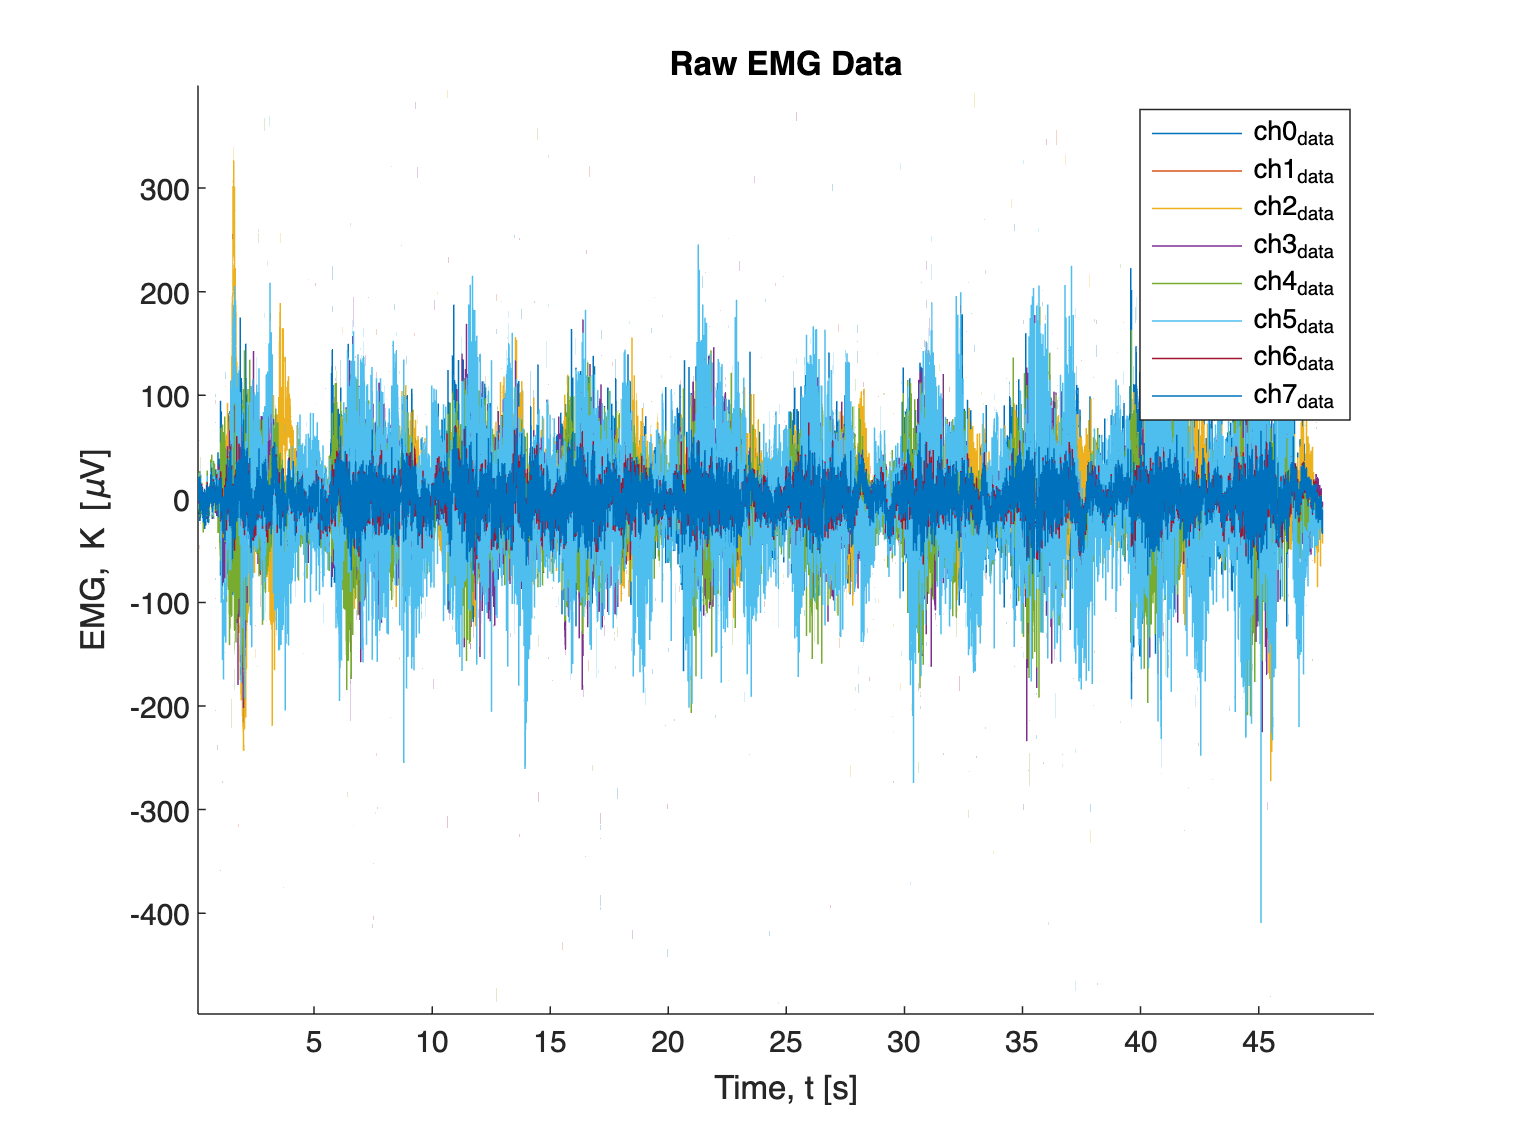

%Plot Raw EMG Data
figure();
hold on;
plot(t, ch0_data)
plot(t, ch1_data) 
plot(t, ch2_data)
plot(t, ch3_data)
plot(t, ch4_data)
plot(t, ch5_data)
plot(t, ch6_data)
plot(t, ch7_data)
legend('ch0_data','ch1_data','ch2_data','ch3_data','ch4_data','ch5_data','ch6_data','ch7_data')
xlabel('Time, t [s]')
ylabel('EMG, K [\muV]')
title('Raw EMG Data')

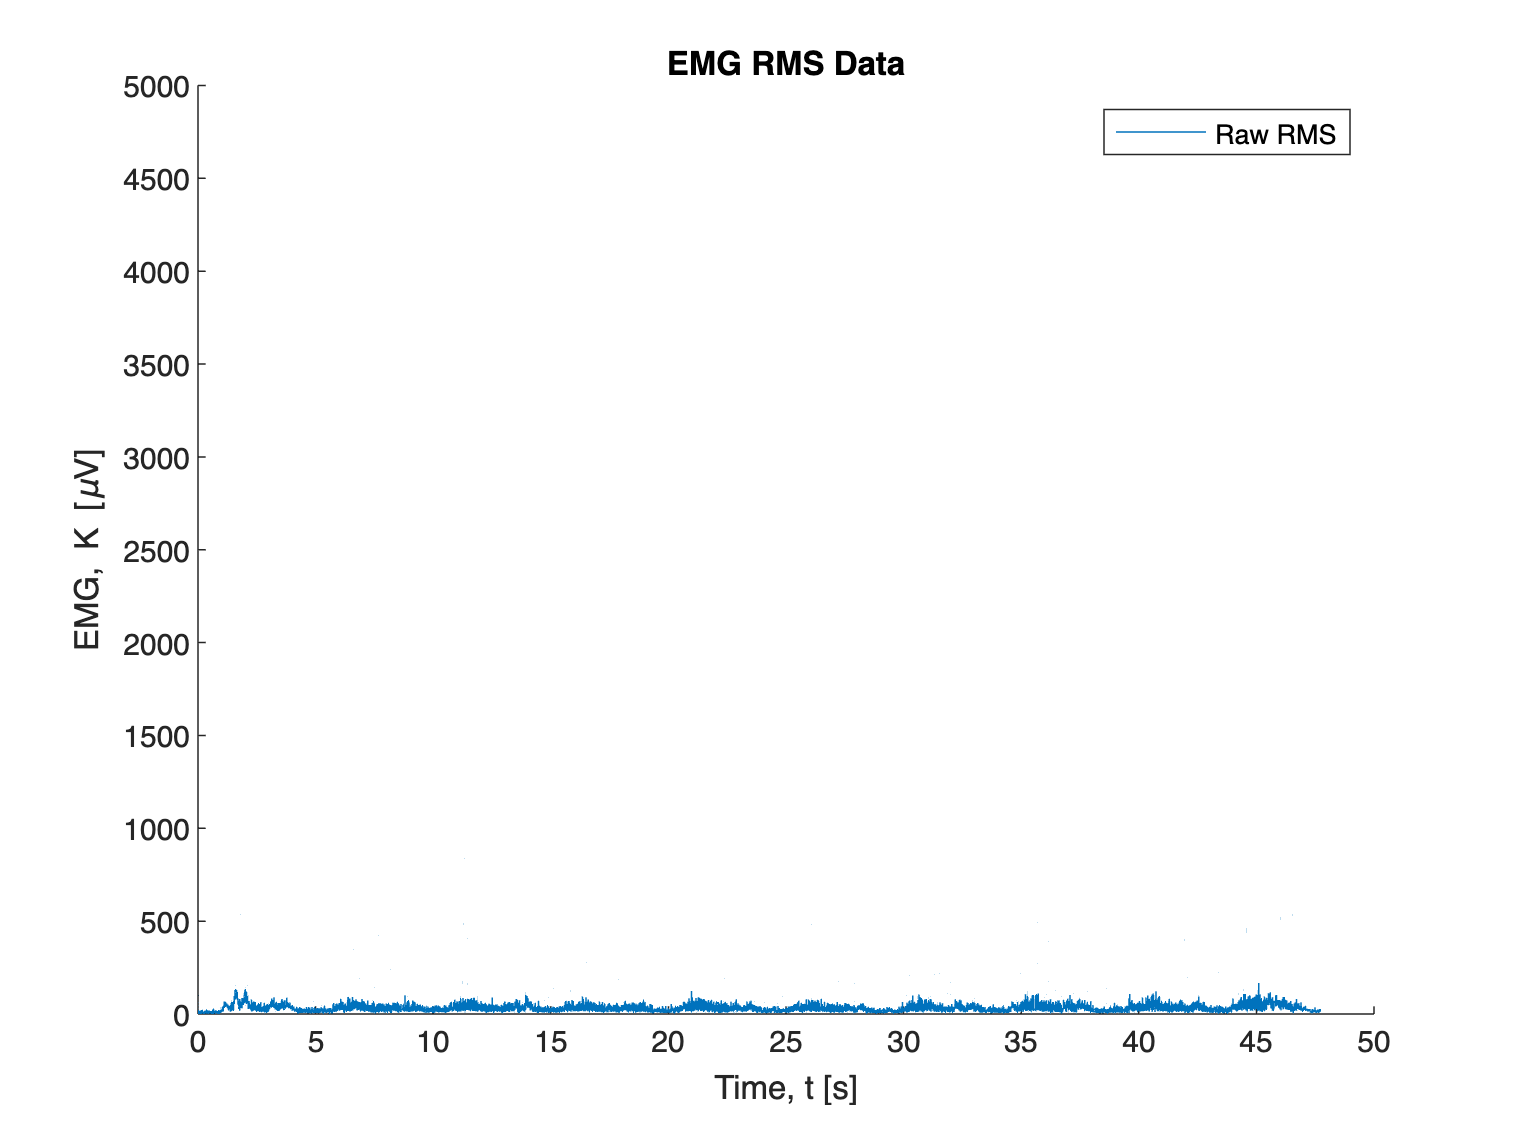


% Calculate EMG RMS Array
%Preallocate the RMS array
EMG_RMS = zeros(size(ch0_data));
EMG_Point_RMS = zeros(size(ch0_data));
% Calculate RMS for each element
for i = 1:numel(ch0_data)
    Point_RMS = [ch0_data(i) ch1_data(i) ch2_data(i) ch3_data(i) ch4_data(i) ch5_data(i) ch6_data(i) ch7_data(i)];
    EMG_RMS(i) = rms(Point_RMS);
end
figure();
hold on;
rms_envelope_EMG = envelope(EMG_RMS, filtervalue, 'rms');
pk_envelope_EMG = envelope(EMG_RMS, filtervalue, 'peak');
plot(t, EMG_RMS)
%plot(t, rms_envelope_EMG)
%plot(t, pk_envelope_EMG)
xlabel('Time, t [s]')
ylabel('EMG, K [\muV]')
title('EMG RMS Data')
legend('Raw RMS')%, 'rms envelope', 'pk envelope')
ylim([0 0.5e4])

## EMG Peak Enveloping

pk_envelope_EMG = envelope(EMG_RMS, filtervalue, 'peak');
sampling_rate = 500;
min_peak_distance = 3.2 * sampling_rate;
[peaks, locations] = findpeaks(pk_envelope_EMG, "MinPeakDistance", min_peak_distance, "MinPeakHeight", 50);
% Sort and select the top 10 peaks
[sorted_peaks, sort_index] = sort(peaks, 'descend');
top_10_peaks = peaks(sort_index(1:min(10, length(sorted_peaks)))); % Ensure there are at least 10 peaks
loc_pk = [t(locations), peaks]

loc_pk =     1.7780  160.3835
    8.8810  107.0623
   13.9840  100.9699
   17.6650   60.5827
   20.9770  124.3543
   26.4490   82.5043
   30.5130  112.7376
   35.6970  110.8654
   40.6860  129.6556
   45.0570  169.4922


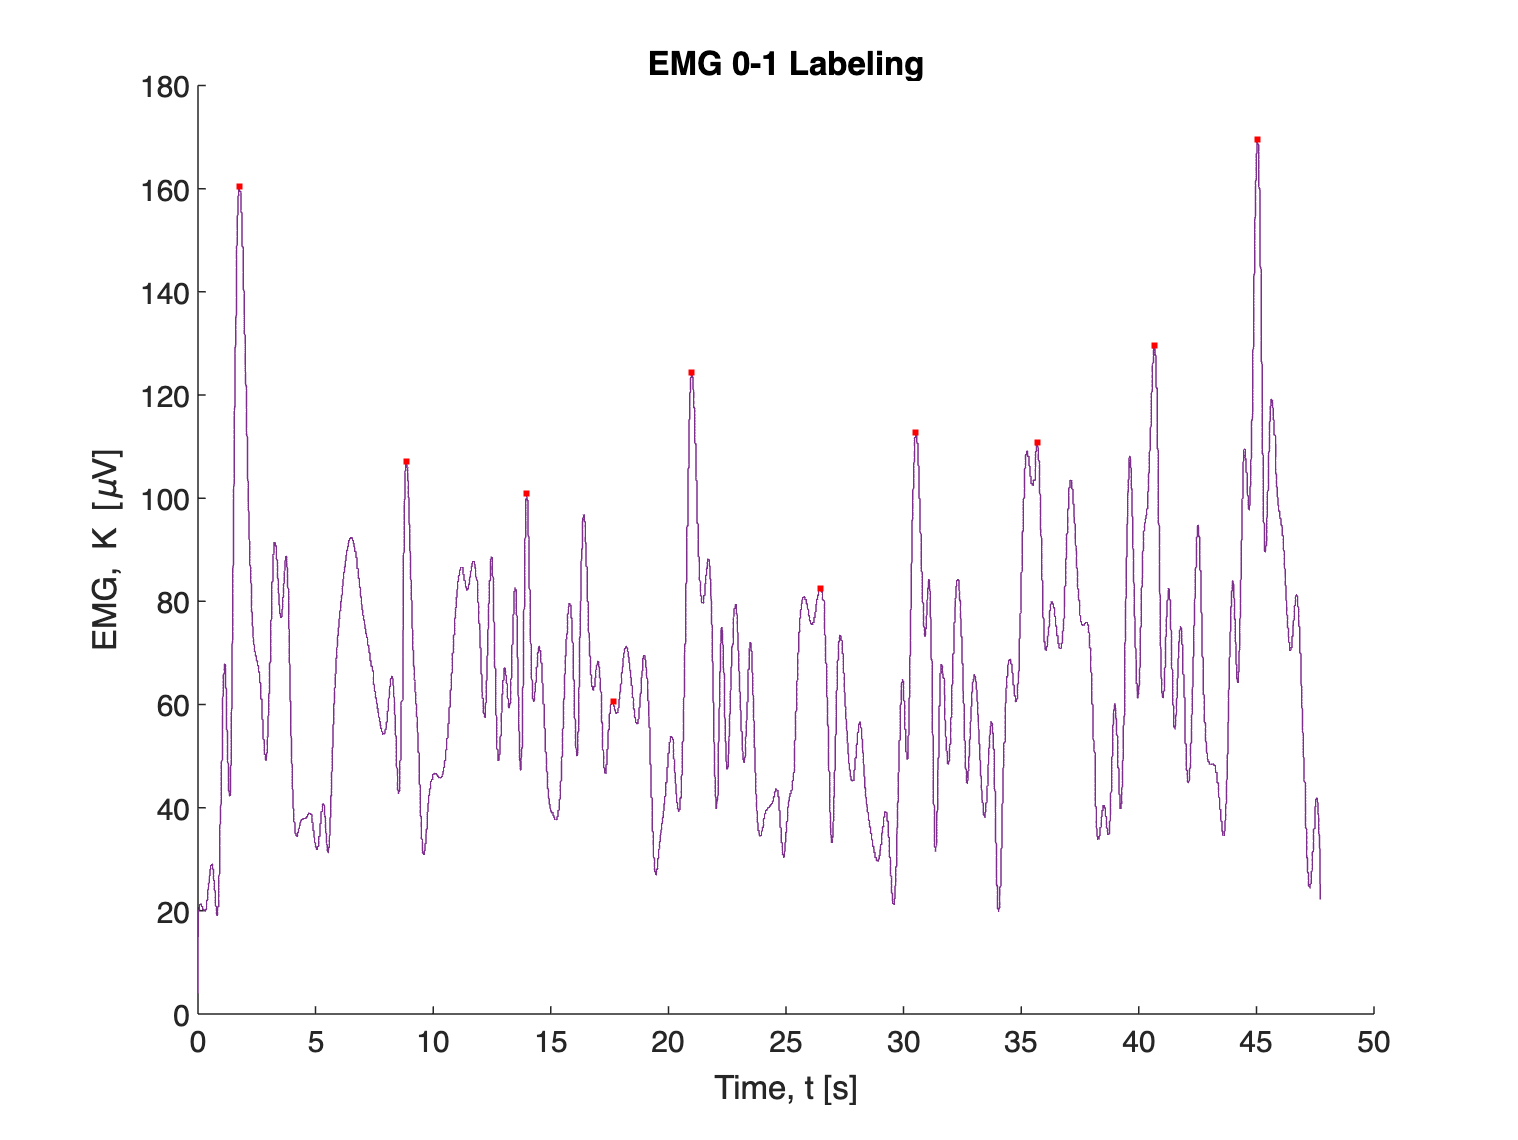


figure();
hold on
plot(t, pk_envelope_EMG)
plot(t(locations(sort_index(1:10))), top_10_peaks, 'g.')
plot(t(locations), peaks, 'r.')

x = loc_pk(:,1);
y = loc_pk(:,2);

plot(t, pk_envelope_EMG)
plot(t(locations(sort_index(1:10))), top_10_peaks, 'g.')
plot(t(locations), peaks, 'r.')

%yline(emgthreshold)
xlabel('Time, t [s]')
ylabel('EMG, K [\muV]')
title('EMG 0-1 Labeling')

%xlim([0 24])
%ylim([0 250])


## Subplotting

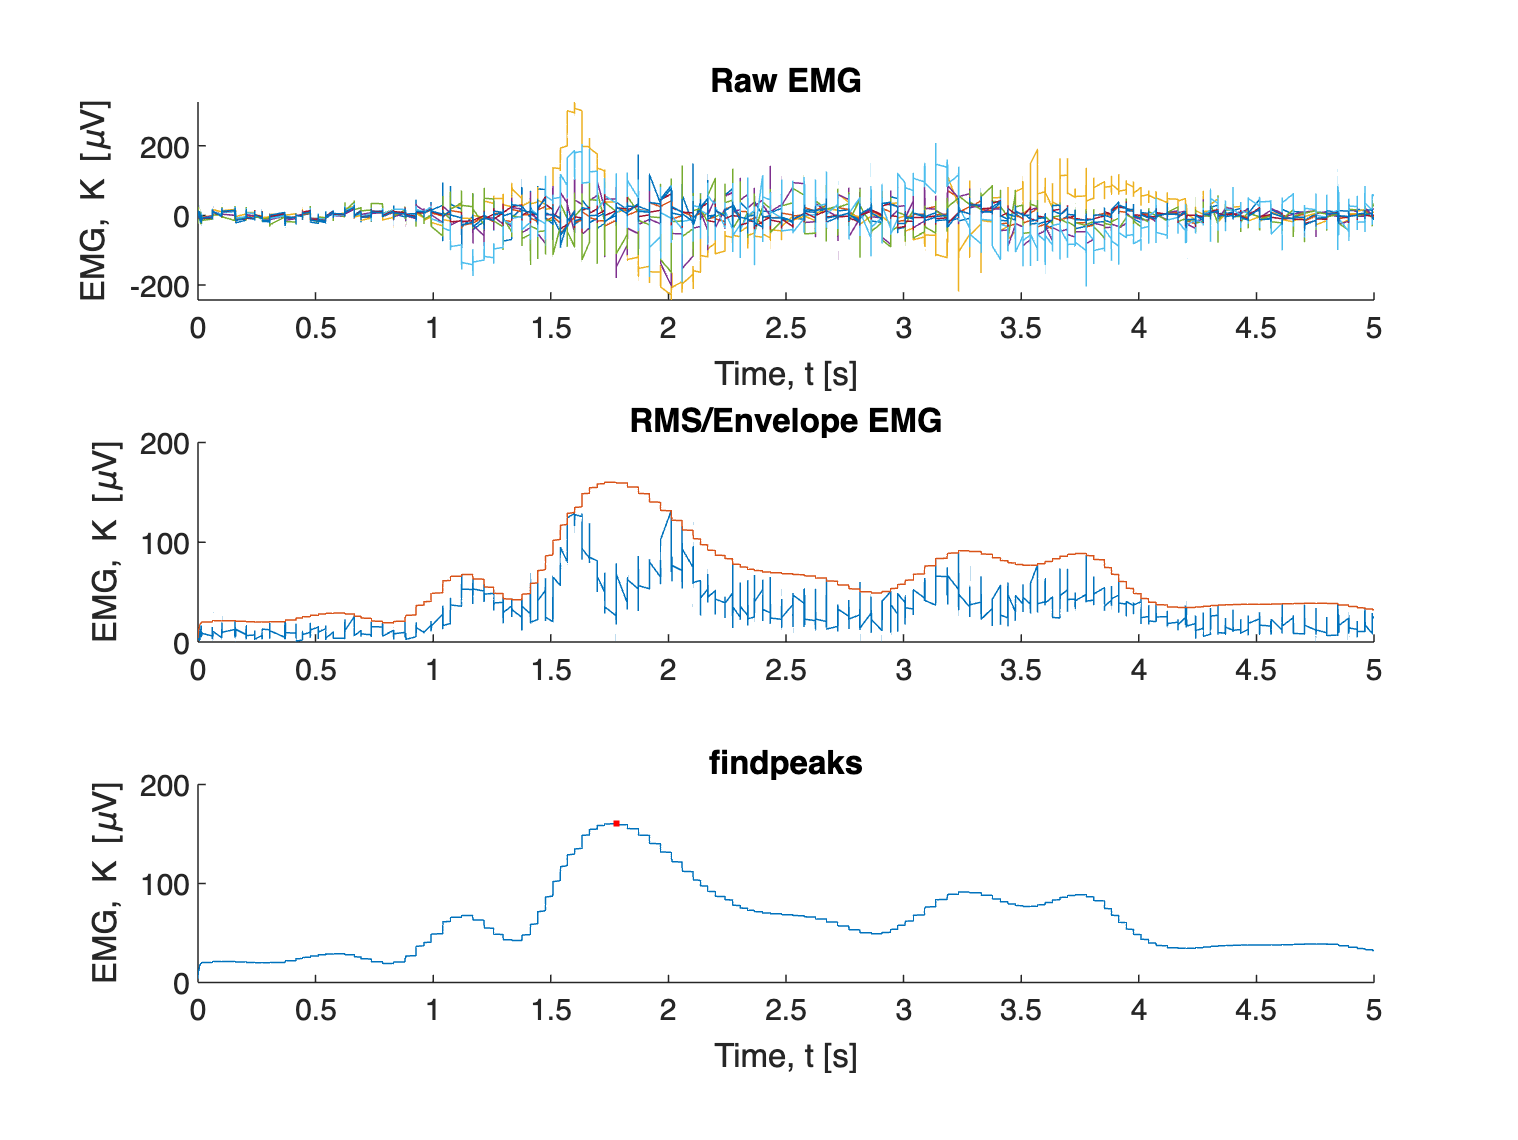

subplot(3,1,1)
hold on;
plot(t, ch0_data)
plot(t, ch1_data) 
plot(t, ch2_data)
plot(t, ch3_data)
plot(t, ch4_data)
plot(t, ch5_data)
plot(t, ch6_data)
plot(t, ch7_data)
ylabel('EMG, K [\muV]')
xlabel('Time, t [s]')
title('Raw EMG')
xlim([0 5])

subplot(3,1,2)
hold on;
plot(t, EMG_RMS)
plot(t, pk_envelope_EMG)
ylabel('EMG, K [\muV]')
title('RMS/Envelope EMG')
xlim([0 5])
subplot(3,1,3)
hold on;
plot(t, pk_envelope_EMG)
plot(t(locations(sort_index(1:10))), top_10_peaks, 'g.')
plot(t(locations), peaks, 'r.')
%yline(emgthreshold)
xlabel('Time, t [s]')
ylabel('EMG, K [\muV]')
title('findpeaks')
xlim([0 5])